# Proyecto Integrador III - Planificación dinámica con A*

Integrantes:  - William Andrade Gonzalez

                     - Glen Alejandro Guerrero Burbano

                     - Yeison Fernando Jimenez Agudelo

## GENERAR EL MAPA Y ENGROSAR OBSTACULOS

Se crea el mapa con los obstaculos

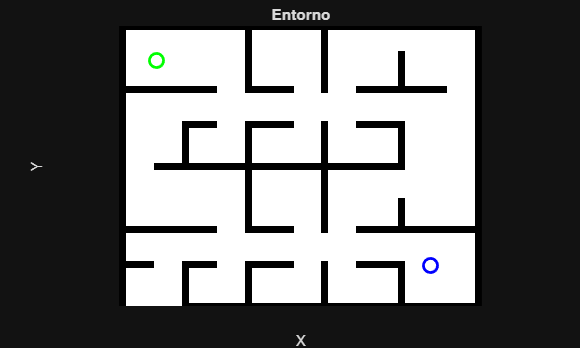

clear; clc; close all;

q_start = [5, 5];
q_goal  = [45, 35]; 

% 1. Generar el mapa inicial
map = dibujarMapa(q_start, q_goal);

[rows, cols] = size(map); 

## PLANIFICACION BASADA EN REJILLA (GRID)

Se construira una rejilla uniforme a partir del mapa y se implementaran los algoritmos de busqueda BFS, DFS, A*. Dibujar cada estrategia de busqueda en una figura independendiente.

Al emplear un tamaño de celda 2, vamos a asumir que no es necesario un mayor engrosamiento de los obstaculos (los caminos pueden rozar las paredes)

% 1) Convertir el mapa a una rejilla más gruesa (tamaño celda = 2).
cell_size = 2;
grid_rows = ceil(rows / cell_size);
grid_cols = ceil(cols / cell_size);

% 2) grid_map = zeros(grid_rows, grid_cols);
for i = 1:grid_rows
    for j = 1:grid_cols
        r_start = (i-1) * cell_size + 1;  r_end = min(i * cell_size, rows); 
        c_start = (j-1) * cell_size + 1;  c_end = min(j * cell_size, cols);
        block = map(r_start:r_end, c_start:c_end);
        if any(block(:) == 1), grid_map(i, j) = 1; end
    end
end

% Convertir inicio y meta a coordenadas de celda
start_node = [ceil(q_start(2)/cell_size), ceil(q_start(1)/cell_size)];
goal_node  = [ceil(q_goal(2)/cell_size), ceil(q_goal(1)/cell_size)];
start_node = max([1 1], min(start_node, [grid_rows, grid_cols]));
goal_node  = max([1 1], min(goal_node,  [grid_rows, grid_cols]));

fprintf('Calculando ruta inicial...\n');

Calculando ruta inicial...


ruta_inicial = a_star_grid(grid_map, start_node, goal_node);

if isempty(ruta_inicial)
    disp('No se encontró una ruta inicial.');
    return;
end

% --- NUEVO: SISTEMA DE HISTORIAL DE RUTAS ---
historial_rutas = {ruta_inicial}; % Guardamos la primera ruta
colores_rutas = lines(10); % Generamos una paleta de colores para las rutas
% 4) GRAFICAR EL ENTORNO DE SIMULACIÓN
figure('Name', 'Simulación A* - Múltiples Replanificaciones', 'Position', [100, 100, 800, 600]); 
axis ij; axis equal; hold on;
axis([0.5 grid_cols+0.5 0.5 grid_rows+0.5]); set(gca, 'Color', 'w');

% Fondo y rejilla
rectangle('Position', [0.5, 0.5, grid_cols, grid_rows], 'FaceColor', 'w', 'EdgeColor', 'k');
for r = 0.5:1:grid_rows+0.5, plot([0.5, grid_cols+0.5], [r, r], 'Color', [0.9 0.9 0.9]); end
for c = 0.5:1:grid_cols+0.5, plot([c, c], [0.5, grid_rows+0.5], 'Color', [0.9 0.9 0.9]); end

% Dibujar obstáculos iniciales
[obs_rows, obs_cols] = find(grid_map == 1);
for k = 1:length(obs_rows)
    fill([obs_cols(k)-0.5, obs_cols(k)+0.5, obs_cols(k)+0.5, obs_cols(k)-0.5], ...
         [obs_rows(k)-0.5, obs_rows(k)-0.5, obs_rows(k)+0.5, obs_rows(k)+0.5], ...
         'k', 'EdgeColor', 'none'); 
end

% Dibujar Inicio y Meta
plot(start_node(2), start_node(1), 'go', 'MarkerSize', 12, 'LineWidth', 3);
plot(goal_node(2), goal_node(1), 'bx', 'MarkerSize', 12, 'LineWidth', 3);

% --- TEXTO Y DIBUJO DE LA RUTA 1 ---
h_rutas = gobjects(1, 10); 
h_rutas(1) = plot(ruta_inicial(:,2), ruta_inicial(:,1), '.-', 'Color', colores_rutas(1,:), 'LineWidth', 2, 'MarkerSize', 12);
text(start_node(2)+0.5, start_node(1)-1, 'Ruta 1', 'Color', colores_rutas(1,:), 'FontWeight', 'bold', 'FontSize', 10, 'BackgroundColor', 'w', 'Margin', 1);

h_robot = plot(ruta_inicial(1,2), ruta_inicial(1,1), 'mo', 'MarkerFaceColor', 'm', 'MarkerSize', 10);
title('Trayectoria 1 (Ruta Inicial)');
drawnow;


## Parametros simulación obstaculos y trayectorias emergentes

ruta_actual = ruta_inicial;
pos_idx = 1;
obstaculos_generados = 0;
max_obstaculos_dinamicos = 1; % Máximo de obstáculos que aparecerán

## Simulación movimiento robot y obstáculos aleatorios

Se ha generado una simulación donde se simula el movimiento del robot con la matriz PATH que representa las coordenadas x,y de los nodos que sigue la trayectoria del robot (Es una movimiento ideal); En la práctica este movimiento deberá ser implementado con los algoritmos de lectura de sensores o odometría e incluso al control del robot. Por ahora se lo hace de una manera ideal desde simulación para enfocarse más en la planificación.

while pos_idx < size(ruta_actual, 1)
    pos_idx = pos_idx + 1;
    nodo_actual = ruta_actual(pos_idx, :);
    
    set(h_robot, 'XData', nodo_actual(2), 'YData', nodo_actual(1));
    drawnow;
    pause(0.1); 
    
    % --- EVENTO ALEATORIO: Probabilidad del 8% por paso de generar obstáculo ---
    % Solo si no hemos llegado al máximo y si estamos lo suficientemente lejos de la meta
    pasos_restantes = size(ruta_actual, 1) - pos_idx;
    if rand() < 0.08 && obstaculos_generados < max_obstaculos_dinamicos && pasos_restantes > 5
        
        obstaculos_generados = obstaculos_generados + 1;
        
        % Colocar obstáculo unos pasos adelante de la posición actual del robot
        distancia_adelante = randi([2, 5]); 
        obs_dyn = ruta_actual(pos_idx + distancia_adelante, :);
        
        % Para asegurar el bloqueo, hacemos un obstáculo de 2x2 celdas
        r_min = max(1, obs_dyn(1)-1); r_max = min(grid_rows, obs_dyn(1)+1);
        c_min = max(1, obs_dyn(2)-1); c_max = min(grid_cols, obs_dyn(2)+1);
        
        % Prevenir que el obstáculo se genere exactamente sobre la meta
        if ~(r_min <= goal_node(1) && goal_node(1) <= r_max && c_min <= goal_node(2) && goal_node(2) <= c_max)
            grid_map(r_min:r_max, c_min:c_max) = 1;
            
            % Dibujarlo en rojo
            for r_obs = r_min:r_max
                for c_obs = c_min:c_max
                    fill([c_obs-0.5, c_obs+0.5, c_obs+0.5, c_obs-0.5], ...
                         [r_obs-0.5, r_obs-0.5, r_obs+0.5, r_obs+0.5], ...
                         'r', 'EdgeColor', 'k');
                end
            end
            title(sprintf('¡Obstáculo # %d detectado!', obstaculos_generados), 'Color', 'r');
            drawnow; pause(0.4);
        end
    end
    
    % --- DETECCIÓN: Verificar si la ruta restante es válida ---
    ruta_invalida = false;
    for k = pos_idx:size(ruta_actual, 1)
        if grid_map(ruta_actual(k, 1), ruta_actual(k, 2)) == 1
            ruta_invalida = true;
            break;
        end
    end
    
    % --- REPLANIFICACIÓN ---
    if ruta_invalida
        num_ruta = length(historial_rutas) + 1;
        disp(['Ruta ' num2str(num_ruta-1) ' bloqueada. Planificando nueva trayectoria']);
        
        % Cambiar el estilo de la ruta vieja a gris punteado
        set(h_rutas(num_ruta-1), 'LineStyle', ':', 'Color', [0.6 0.6 0.6], 'Marker', 'none', 'LineWidth', 1.5);
        
        % Calcular nueva ruta desde nodo actual
        nueva_ruta = a_star_grid(grid_map, nodo_actual, goal_node);
        
        if isempty(nueva_ruta)
            title('ERROR: El robot está completamente atrapado.', 'Color', 'r');
            break;
        else
            ruta_actual = nueva_ruta;
            historial_rutas{end+1} = ruta_actual; % Añadir al historial
            pos_idx = 1; 
            
            % 2. Dibujar la nueva ruta con un nuevo color
            color_nuevo = colores_rutas(mod(num_ruta-1, size(colores_rutas,1))+1, :);
            h_rutas(num_ruta) = plot(ruta_actual(:,2), ruta_actual(:,1), '.-', 'Color', color_nuevo, 'LineWidth', 2, 'MarkerSize', 12);
            
            % 3. --- NUEVO: TEXTO EN EL INICIO DE LA NUEVA RUTA ---
            % Desplazamos ligeramente el texto (+0.5, -1) para que no tape la línea
            texto_ruta = sprintf('Ruta %d', num_ruta);
            text(nodo_actual(2)+0.5, nodo_actual(1)-1, texto_ruta, 'Color', color_nuevo, 'FontWeight', 'bold', 'FontSize', 10, 'BackgroundColor', 'w', 'Margin', 1);
            
            title(sprintf('Trayectoria %d planificada. Reanudando...', num_ruta), 'Color', color_nuevo);
            drawnow; pause(0.5);

            % % Dibujar nueva ruta con el siguiente color de la paleta
            % color_nuevo = colores_rutas(mod(num_ruta, 10)+1, :);
            % h_rutas(num_ruta) = plot(ruta_actual(:,2), ruta_actual(:,1), '.-', 'Color', color_nuevo, 'LineWidth', 2, 'MarkerSize', 12);
            % 
            % title(sprintf('Trayectoria %d calculada. Reanudando...', num_ruta), 'Color', color_nuevo);
            % drawnow; pause(0.5);
        end
    end
end

Ruta 1 bloqueada. Planificando nueva trayectoria


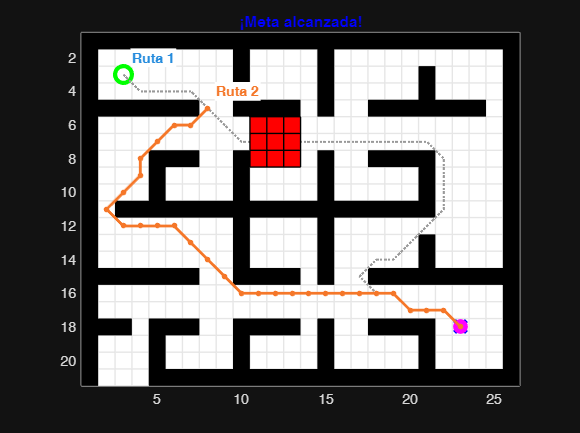


if isequal(nodo_actual, goal_node)
    title('¡Meta alcanzada!', 'Color', 'b');
end
hold off;

xlim([0.5 26.5])
ylim([0.5 21.5])
 
ax = gca;
chart = ax.Children(224);
datatip(chart,18.5,0.5);

hDataTip = findobj(gca,"DataIndex",1);
delete(hDataTip)


%% --- REPORTE FINAL ---
fprintf('\n--- RESUMEN DE PLANIFICACIÓN ---\n');


--- RESUMEN DE PLANIFICACIÓN ---


fprintf('Obstáculos nuevos detectados: %d\n', obstaculos_generados);

Obstáculos nuevos detectados: 1


fprintf('Total de trayectorias planificadas: %d\n', length(historial_rutas));

Total de trayectorias planificadas: 2


for i = 1:length(historial_rutas)
    distancia = size(historial_rutas{i}, 1) - 1;
    fprintf('Trayectoria %d: Longitud de %d pasos.\n', i, distancia);
end

Trayectoria 1: Longitud de 33 pasos.
Trayectoria 2: Longitud de 28 pasos.


fprintf('--------------------------------\n');

--------------------------------


## FUNCIÓN A_STAR_GRID

function ruta = a_star_grid(grid, start_cell, goal_cell)
    [rows, cols] = size(grid);
    g_score = inf(rows, cols);
    f_score = inf(rows, cols);
    g_score(start_cell(1), start_cell(2)) = 0;
    
    h_start = norm(start_cell - goal_cell); 
    f_score(start_cell(1), start_cell(2)) = h_start;
    
    openList = [start_cell, h_start]; 
    parent = cell(rows, cols);
    
    moves = [-1,  0; 1,  0; 0,  1; 0, -1; -1, -1; -1,  1; 1, -1; 1,  1]; 
    move_cost = [1, 1, 1, 1, sqrt(2), sqrt(2), sqrt(2), sqrt(2)];
    found = false;
    
    while ~isempty(openList)
        [~, idx] = min(openList(:, 3));
        current = openList(idx, 1:2);
        openList(idx, :) = [];
        
        if isequal(current, goal_cell)
            found = true; break;
        end
        
        for k = 1:8
            nr = current(1) + moves(k,1); 
            nc = current(2) + moves(k,2);
            
            if nr>0 && nr<=rows && nc>0 && nc<=cols && grid(nr,nc)==0
                tentative_g = g_score(current(1), current(2)) + move_cost(k);
                if tentative_g < g_score(nr, nc)
                    parent{nr, nc} = current;
                    g_score(nr, nc) = tentative_g;
                    h = sqrt((nr - goal_cell(1))^2 + (nc - goal_cell(2))^2);
                    f_score(nr, nc) = tentative_g + h;
                    
                    in_open = false;
                    for m = 1:size(openList, 1)
                        if openList(m,1)==nr && openList(m,2)==nc
                            openList(m,3) = f_score(nr, nc);
                            in_open = true; break;
                        end
                    end
                    if ~in_open
                        openList = [openList; nr, nc, f_score(nr, nc)];
                    end
                end
            end
        end
    end
    ruta = reconstruct_path(parent, start_cell, goal_cell, found);
end

## Función auxiliar

Utilizada para reconstruir ruta

function ruta = reconstruct_path(parent, start, goal, found)
    ruta = [];
    if found
        curr = goal;
        while ~isempty(curr)
            ruta = [curr; ruta];
            if isequal(curr, start)
                break;
            end
            curr = parent{curr(1), curr(2)};
        end
    end
end
